% boost converter modeling
clear all
syms R_c C R_L L R_eq i_sa v_C(t) i_L(t) i_pv v_pv V_dc alpha beta didt d s Cg

% eqn_kvl1 = R_c*C*diff(v_C,t) + v_C== R_L*i_L + L*diff(i_L,t)
% eqn_kcl1 = i_pv == C*diff(v_C,t) + i_L
% eqn_kvl2 = R_c*C*diff(v_C,t) + v_C == R_L*i_L + L*diff(i_L,t) + V_dc
% eqn_kcl2 = i_pv == C*diff(v_C,t) + i_L
alpha = 1/R_eq;
beta = i_sa

$$beta = i_{\mathrm{sa}}$$

A_on = [-1/L*(R_c/(1+alpha*R_c)+R_L), 1/L*(1-alpha*R_c/(1+alpha*R_c));
    -1/(C*(1+alpha*R_c)), -alpha/(C*(1+alpha*R_c))]

$$A\_on = \left(\begin{array}{cc} -\frac{R_{L}+\frac{R_{c}}{\frac{R_{c}}{R_{\mathrm{eq}}}+1}}{L} & -\frac{\frac{R_{c}}{R_{\mathrm{eq}}\,\left(\frac{R_{c}}{R_{\mathrm{eq}}}+1\right)}-1}{L}\\ -\frac{1}{C\,\left(\frac{R_{c}}{R_{\mathrm{eq}}}+1\right)} & -\frac{1}{C\,R_{\mathrm{eq}}\,\left(\frac{R_{c}}{R_{\mathrm{eq}}}+1\right)} \end{array}\right)$$

B_on = [beta*R_c/(L*(1+alpha*R_c))
    beta/(C*(1+alpha*R_c))]

$$B\_on = \left(\begin{array}{c} \frac{R_{c}\,i_{\mathrm{sa}}}{L\,\left(\frac{R_{c}}{R_{\mathrm{eq}}}+1\right)}\\ \frac{i_{\mathrm{sa}}}{C\,\left(\frac{R_{c}}{R_{\mathrm{eq}}}+1\right)} \end{array}\right)$$

A_off = [-1/L*(R_c/(1+alpha*R_c)+R_L), 1/L*(1-alpha*R_c/(1+alpha*R_c));
    -1/(C*(1+alpha*R_c)), -alpha/(C*(1+alpha*R_c))]

$$A\_off = \left(\begin{array}{cc} -\frac{R_{L}+\frac{R_{c}}{\frac{R_{c}}{R_{\mathrm{eq}}}+1}}{L} & -\frac{\frac{R_{c}}{R_{\mathrm{eq}}\,\left(\frac{R_{c}}{R_{\mathrm{eq}}}+1\right)}-1}{L}\\ -\frac{1}{C\,\left(\frac{R_{c}}{R_{\mathrm{eq}}}+1\right)} & -\frac{1}{C\,R_{\mathrm{eq}}\,\left(\frac{R_{c}}{R_{\mathrm{eq}}}+1\right)} \end{array}\right)$$

B_off = [1/L*(beta*R_c/(1+alpha*R_c) - V_dc)
    beta/(C*(1+alpha*R_c))]

$$B\_off = \left(\begin{array}{c} -\frac{V_{\mathrm{dc}}-\frac{R_{c}\,i_{\mathrm{sa}}}{\frac{R_{c}}{R_{\mathrm{eq}}}+1}}{L}\\ \frac{i_{\mathrm{sa}}}{C\,\left(\frac{R_{c}}{R_{\mathrm{eq}}}+1\right)} \end{array}\right)$$

% A = A_avg = Aon*d + Aoff*(1-d)
% B = B_avg = Bon*d + Boff*(1-d)
A = simplify(A_on*d + A_off*(1-d))

$$A = \left(\begin{array}{cc} -\frac{R_{L}\,R_{c}+R_{L}\,R_{\mathrm{eq}}+R_{c}\,R_{\mathrm{eq}}}{L\,\left(R_{c}+R_{\mathrm{eq}}\right)} & \frac{R_{\mathrm{eq}}}{L\,\left(R_{c}+R_{\mathrm{eq}}\right)}\\ -\frac{R_{\mathrm{eq}}}{C\,\left(R_{c}+R_{\mathrm{eq}}\right)} & -\frac{1}{C\,\left(R_{c}+R_{\mathrm{eq}}\right)} \end{array}\right)$$

B = [V_dc/L;
    0]

$$B = \left(\begin{array}{c} \frac{V_{\mathrm{dc}}}{L}\\ 0 \end{array}\right)$$


phi = inv(s*eye(2) - A);
Ci = [1, 0];
Cv = [0, 1];
G_di = simplify(Ci*phi*B)

$$G\_di = \frac{V_{\mathrm{dc}}\,\left(C\,R_{c}\,s+C\,R_{\mathrm{eq}}\,s+1\right)}{R_{L}+R_{\mathrm{eq}}+L\,s+C\,L\,R_{c}\,s^{2}+C\,L\,R_{\mathrm{eq}}\,s^{2}+C\,R_{L}\,R_{c}\,s+C\,R_{L}\,R_{\mathrm{eq}}\,s+C\,R_{c}\,R_{\mathrm{eq}}\,s}$$

G_dv = simplify(Cv*phi*B)

$$G\_dv = -\frac{R_{\mathrm{eq}}\,V_{\mathrm{dc}}}{R_{L}+R_{\mathrm{eq}}+L\,s+C\,L\,R_{c}\,s^{2}+C\,L\,R_{\mathrm{eq}}\,s^{2}+C\,R_{L}\,R_{c}\,s+C\,R_{L}\,R_{\mathrm{eq}}\,s+C\,R_{c}\,R_{\mathrm{eq}}\,s}$$

% % double loop
% clear all;

% % PVPCS DC/DC
% s = tf('s');
% % syms s
% fs = 20e+3; % 20kHz
% L = 580e-6; % 580uH
% RL = 0.03;   % 30m ohm
% C = 15e-6; % 15uF
% RC = 9.7e-3;  % 9.7m ohm
% Req = 20.8; % 20.8ohm
% Vdc = 400;  % 400V

% % Transfer Function CURRENT
% delta = L*C*(Req+RC)*s^2+(C*Req*RC+C*Req*RL+C*RC*RL+L)*s + Req+RL;
% 
% Gi= Vdc*(C*(Req+RC)*s+1)/delta

Gi =
 
            0.1249 s + 400
  ----------------------------------
  1.81e-07 s^2 + 0.0005924 s + 20.83
 
연속시간 전달 함수입니다.
모델 속성


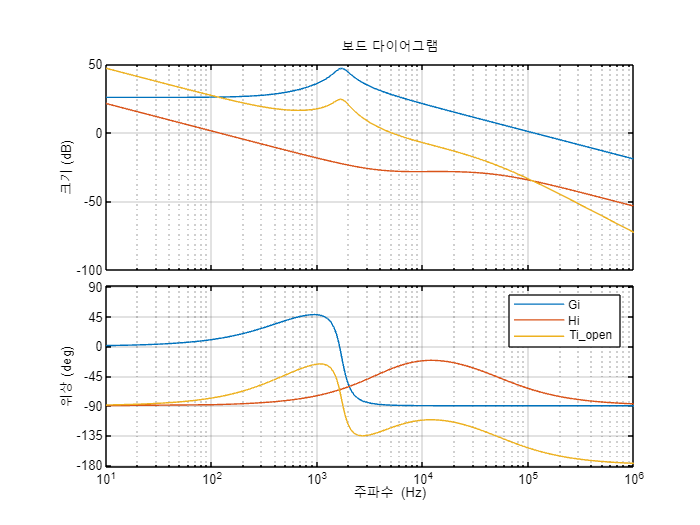

% 
% % H(s)
% % Gi의 공진주파수 약 190Hz
% % Gi의 좌반면 영점 약 16.21Hz
% ifz1 = 5000; 
% ifz2 = 5000; 
% ifp1 = 9200; 
% ifp2 = 50000; 
% 
% iwz1 = 2*pi*ifz1; 
% iwz2 = 2*pi*ifz2; 
% iwp1 = 2*pi*ifp1; 
% iwp2 = 2*pi*ifp2; 
% Ki = 724;
% 
% Hi = Ki*(s/iwz1+1)*(s/iwz2+1)/(s*(s/iwp1+1)*(s/iwp2+1));
% Ti_open = Hi*Gi;
% 
% % BODE
% P = bodeoptions; P.FreqUnits = 'Hz';
% bodeplot(Gi,P);
% hold on
% bodeplot(Hi,P);
% bodeplot(Ti_open,P);
% hold off
% legend();
% grid;

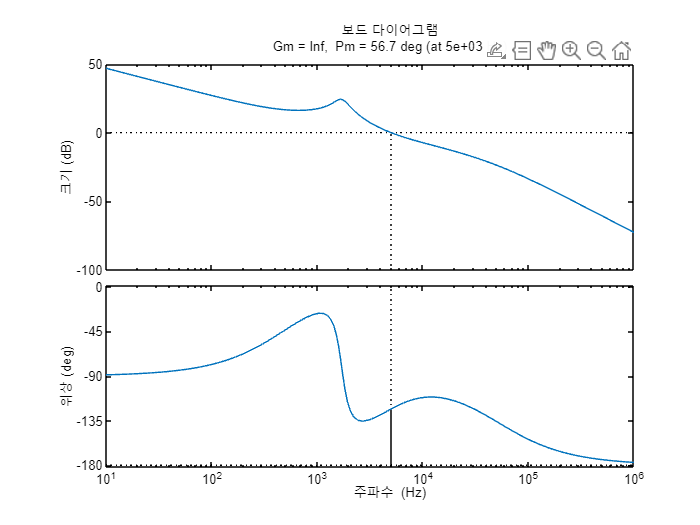

% 
% margin(Ti_open,P)

% % Transfer Function VOLTAGE
% delta = L*C*(Req+RC)*s^2+(C*Req*RC+C*Req*RL+C*RC*RL+L)*s + Req+RL;
% Gv= -Vdc*(C*Req*RC*s+Req)/delta

Gv =
 
          -0.001211 s - 8320
  ----------------------------------
  1.81e-07 s^2 + 0.0005924 s + 20.83
 
연속시간 전달 함수입니다.
모델 속성


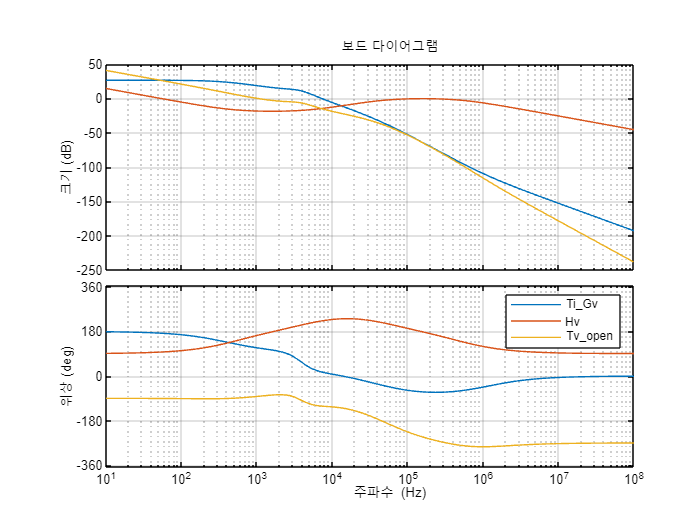

% 
% Ti_closed = Hi/(1 + Hi*Gi);
% 
% % H(s)
% % Gi의 공진주파수 약 190Hz
% % Gi의 좌반면 영점 약 16.21Hz
% vfz1 = 500; 
% vfz2 = 5000; 
% vfp1 = 50000; 
% vfp2 = 500000; 
% 
% vwz1 = 2*pi*vfz1; 
% vwz2 = 2*pi*vfz2; 
% vwp1 = 2*pi*vfp1; 
% vwp2 = 2*pi*vfp2; 
% 
% Hv = -327*(s/vwz1+1)*(s/vwz2+1)/(s*(s/vwp1+1)*(s/vwp2+1));
% 
% Ti_Gv = Ti_closed*Gv;
% 
% Tv_open = Ti_Gv*Hv;
% 
% 
% % BODE
% P = bodeoptions; P.FreqUnits = 'Hz';
% bodeplot(Ti_Gv,P);
% hold on
% bodeplot(Hv,P); 
% bodeplot(Tv_open,P);
% hold off
% legend();
% grid;

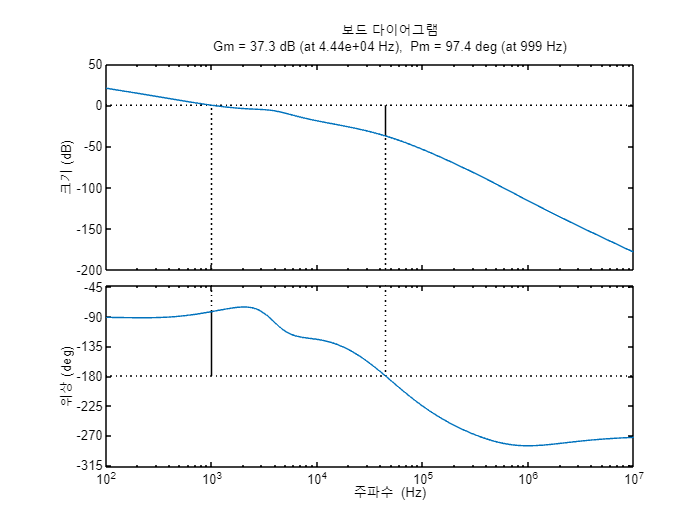

% 
% margin(Tv_open,P)

% % % reference
% % Vpv_ref = 300; 
% % Ipv_ref = 10;
% % 
% % % SISOTOOL tf([1 0], 0)
% % T = sisoinit(6); 
% % T.F.Value = Vpv_ref;
% % T.C1.Value = Hv;
% % T.C2.Value = Hi;
% % T.G1.Value = tf(1, 1);
% % T.G2.Value = Gv;
% % T.H1.Value = Gi;
% % T.H2.Value = tf(1, 1);
% % 
% % sisotool(T)